# Tutorial do lab "Rozwiązywanie równań różniczkowych"

**Zakres ćwiczenia: rozwiązywanie równań różniczkowych (dalej skrótowo "RR"), długość kroku, dokładność rozwiązania, granica stabilności.**

Analityczne rozwiązenie równania różniczkowego polega na znalezieniu funkcji, która spełnia to równanie. W praktyce inżynierskiej często spotykamy się z RR, które nie dają się rozwiązać w sposób analityczny (lub znalezienie takiego rozwiązania jest wystarczająco trudne, żeby nie opłacało się tego robić). W takim przypadku zazwyczaj przychodzą nam z pomocą numeryczne metody rozwiązywania RR.

**Rozwiązanie RR w sensie numerycznym polega na wyliczeniu wektora wartości (na podstawie warunków początkowych), który w wystarczającym stopniu przybliża nam funkcję opisaną równaniem różniczkowym.**

Pochodna w punkcie z definicji mówi nam o tym, jak szybko funkcja przyrasta w sąsiedztwie danego argumentu. To znaczy, że znając wartość funkcji i jej pochodnej w punkcie *t0*, jesteśmy w stanie wyznaczyć wartość tej funkcji w bliskim otoczeniu *t0* (ściśle w nieskończenie bliskim otoczeniu) – np. w punkcie *t0*+𝛿*t*, gdzie 𝛿*t*→0. Matematycy zapisaliby to:


$$f\prime {\left(t_0 \right)}≝\lim_{\textrm{δt}\to 0} \frac{f{\left(t_0 +\delta t\right)}-f{\left(t\right)}}{\delta t}\delta \textrm{t}\;\ \ \ \ \ \ \ \underset{\ \delta t\to 0}{\Rightarrow} \ \ \ \ \ \ \ \ f{\left(t_0 +\delta t\right)}=f{\left(t_0 \right)}+\delta \textrm{t*}f^{\prime } {\left(t_0 \right)}$$


Znając wartość funkcji w punkcie *t1*=*t0*+𝛿*t* możemy z naszego równania wyznaczyć pochodną w punkcie *t1, to jest* 𝑓′(*t1*), a następnie analogicznie jak przed chwilą 𝑓(*t2*) oraz 𝑓′(*t2*), gdzie *t2*=*t1*+𝛿*t* itd. W ten sposób wykonując nieskończenie wiele ruchów, dokładnie odtworzymy wykres funkcji 𝑓(*t*).

**W praktyce numerycznej oczywiście nie jest możliwe wykonanie nieskończenie wielu obliczeń, jak i reprezentowanie nieskończenie małych liczb. Jednak stosując bardzo dużo bardzo małych kroków, osiągniemy wykres funkcji, który będzie bardzo podobny do wykresu funkcji 𝑓(*****t*****).**

W trakcie ćwiczenia badać będziemy badać:

- jak bardzo podobny będzie nasz „wyliczony” wykres do rzeczywistego wykresu szukanej funkcji, w zależności od dobranej wielkości kroku (**dokładność rozwiązania numerycznego**),

- kiedy metoda w ogóle pozwala osiągnąć rozwiązanie (**stabilność metody**),

- jak zmodyfikować formułę zaproponowaną na podstawie matematycznej definicji pochodnej w powyższych akapitach (metoda otwarta Eulera), aby zadowalająco dokładne rozwiązanie otrzymać w możliwie najlepszym czasie (**złożoność obliczeniowa metody**).

Do interpretacji zjawisk obserwowanych w trakcie laboratorium potrzebne jest zrozumienie pojęcia **rzędu metody**.

#### Zalecany sposób wykonania poniższych programów przykładowych:

1) Wybrać z górnego paska opcję "VIEW" -> "Hide Code",

2) Uruchomić program wciskając przycisk "WYKONAJ",

3) Obejrzeć wyniki,

4) Powtórzyćpunkty 2-3 dla różnych wariantów zadania,

5) Przeanalizować kod (zmienić opcję "VIEW"),

6) Po tym wszystkim zaleca się samodzielnie zmodyfikować (lub napisać nowy) kod, w którym np. zaimplementowane zostaną inne metody numeryczne rozwiązania RR (np. zamknięta Eulera, trapezów itp.).

POWODZENIA!

### Przykład 1. Porównanie rozwiązania dokładnego z rozwiązaniem uzyskanym otwartą metodą Eulera dla różnych długości kroku 

Przykład 1 ilustruje zastosowanie prostej metody stałokrokowej oraz zależność dokładności rozwiązania od długości kroku w takim wypadku. 

Analizowaną funkcję i długość kroku należy wybrać we właściwym polu. Skalę wykresu należy dobrać tak, aby najlepiej widoczne były obserwowane zjawiska.

Proszę znaleźć ten wariant, przy którym zaobserwować można niestabilność metody otwartej Eulera.

clc;clear all;close all % to dobry poczatek kazdego skryptu
disp('Start')

Start


 % RUN przykład 1

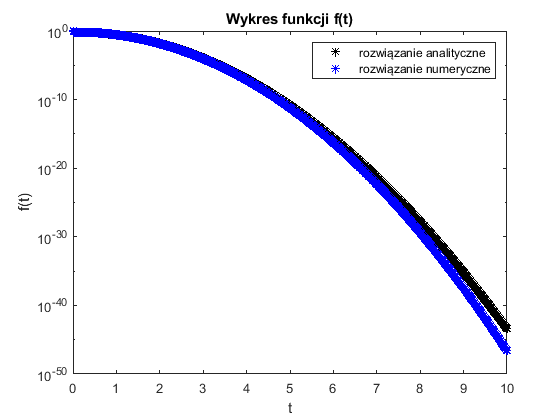

% Przykład 1
a=0;    %początek przedziału
b=10;   %koniec przedziału
y0=1;    %warunek początkowy 
Krok=3;
switch Krok
    case 1
        h=1;
    case 2
        h=0.1;
    case 3
        h=0.01;
    case 4
        h=0.001;
    case 5
        h=1e-5;
end
N=(b-a)/h+1; %długość wyznaczanego wektora (zależna od h) - liczba punktów, dla których wyznaczamy (przybliżoną) wartość szukanej funkcji.
T=linspace(a, b, (b-a)/h+1); %wektor zmiennej nizależnej t (od a do b z krokiem ~h)

RR=1;
switch RR
    case 1
        f=@(t) exp(-t.^2);      %wzór f z rozwiązania analitycznego - służy do kontrolnego wyznaczenia wartości dokładnej - często niedostępna w praktyce inżynierskiej.
        f_prim=@(t, y) -2*y*t;  %wzór f' z postaci kanonicznej RR (ta funkcja zostanie zaimplementowane w metodzie numerycznej)
    case 2   
        f=@(t) 2+(y0-2)*exp((-2)*t./3);     %wzór f z rozwiązania analitycznego - służy do kontrolnego wyznaczenia wartości dokładnej - często niedostępna w praktyce inżynierskiej.
        f_prim=@(t,y) (4-2*y)/3;            %wzór f' z postaci kanonicznej RR (ta funkcja zostanie zaimplementowane w metodzie numerycznej).
end

%%%wyznaczenie dokładnych wartości szukanej funkcji (korzystając z wzoru analitycznego)
Y_dokl=f(T); 
%%%

%%%wyznaczenie wartości przybliżonych szukanej funkcji (rozwiązanie numeryczne RR):
Y_num(1)=y0;
for i=2:N
    Y_num(i)=Y_num(i-1)+h*f_prim(T(i-1),Y_num(i-1));  %implementacja metody otwartej Eulera
end
%%%


%%%wykresy funkcji f(t) z różnego rodzaju skalą na osiach
Skala_f=2;
switch Skala_f
    case 1
        plot(T,Y_dokl, 'k*', T, Y_num, 'b*')
        title('Wykres funkcji f(t)')
        xlabel('t')
        ylabel('f(t)')
        legend("rozwiązanie analityczne", "rozwiązanie numeryczne", "Box","on")
    case 2
        semilogy(T,Y_dokl, 'k*', T, Y_num, 'b*')
        title('Wykres funkcji f(t)')
        xlabel('t')
        ylabel('f(t)')
        legend("rozwiązanie analityczne", "rozwiązanie numeryczne", "Box","on")
    case 3
        semilogx(T,Y_dokl, 'k*', T, Y_num, 'b*')
        title('Wykres funkcji f(t)')
        xlabel('t')
        ylabel('f(t)')
        legend("rozwiązanie analityczne", "rozwiązanie numeryczne", "Box","on")
end

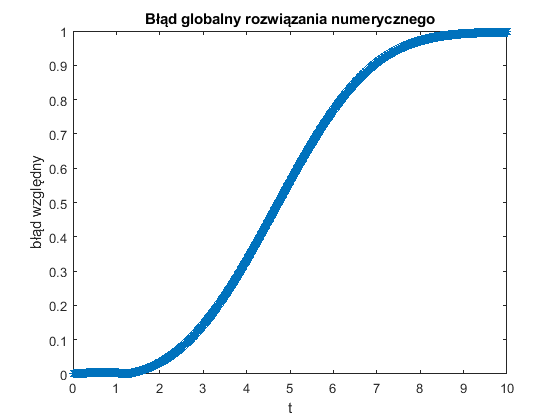

%%% 

Err=abs((Y_num-Y_dokl)./Y_dokl); %wektor błędu względnego rozwiązania numerycznego

%%%wykresy błędu względnego z różnego rodzaju skalą na osiach
Skala_err=1;
switch Skala_err
    case 1
        plot(T,Err, '*')
        title('Błąd globalny rozwiązania numerycznego')
        xlabel('t')
        ylabel('błąd względny')
    case 2
        semilogy(T,Err, '*')
        title('Błąd globalny rozwiązania numerycznego')
        xlabel('t')
        ylabel('błąd względny')
    case 3
        semilogx(T,Err, '*')
        title('Błąd globalny rozwiązania numerycznego')
        xlabel('t')
        ylabel('błąd względny')
end

%%% 
disp('Koniec przykladu 1')

Koniec przykladu 1


## Przykład 2. Porównanie stabilności i złożoności obliczeniowej przykładowych metod numerycznych w zależności od długości kroku. 

Rozwiązywane będzie RR postaci: dy/dt=(4-2y)/3.

disp('Start')

Start


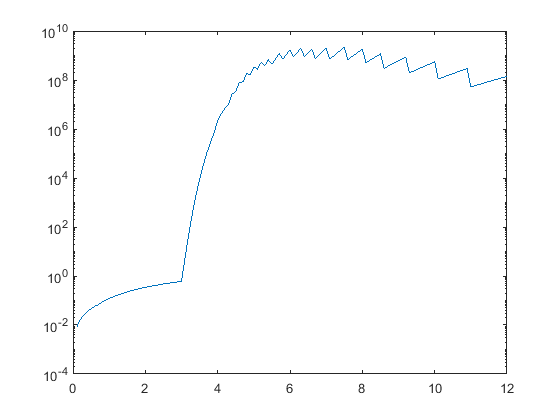

 % RUN przykład 2
clear all;
close all;

% Przykład 2
a=0;    %początek przedziału
b=120;   %koniec przedziału
y0=1;    %warunek początkowy

f=@(t) 2+(y0-2)*exp((-2)*t./3);     %wzór f z rozwiązania analitycznego - służy do kontrolnego wyznaczenia wartości dokładnej - często niedostępna w praktyce inżynierskiej.
f_prim=@(t,y) (4-2*y)/3;            %wzór f' z postaci kanonicznej RR (ta funkcja zostanie zaimplementowane w metodzie numerycznej).
j=1;
h_gr_index=1;
flag=0;
for h = 12:-0.1:0.1                       %różna długość kroku (zakres i skok wybrane arbitralnie)
    N=(b-a)/h+1;                        %długość wyznaczanego wektora (zależna od h) - liczba punktów, dla których wyznaczamy (przybliżoną) wartość szukanej funkcji.
    T=linspace(a, b, (b-a)/h+1);        %wektor zmiennej nizależnej t (od a do b z krokiem ~h)
    Y_dokl=f(T);                        %wyznaczenie dokładnych wartości szukanej funkcji (korzystając z wzoru analitycznego)

    %%%wyznaczenie wartości przybliżonych szukanej funkcji (rozwiązanie numeryczne RR):
    Y_num(1)=y0;
    for i=2:N
        Y_num(i)=Y_num(i-1)+h*f_prim(T(i-1),Y_num(i-1));  %implementacja metody otwartej Eulera
    end
    %%%
    
    Err=abs((Y_num-Y_dokl)./Y_dokl); %wektor globalnego błędu względnego rozwiązania numerycznego
    
    Err_od_h(j)=max(Err);
    j=j+1;
end

semilogy(linspace(12,0.1,120),Err_od_h)

**Funkcje MATLABA z którymi warto się zapoznać przed realizacją ćwiczenia:** grupa funkcji **ode** (np. **ode45**, **ode23**, **ode15s**) wraz z obsługą ich parametrów (**odeset**), prawdopodobnie będzie trzeba też zaimplementować własną funkcję realizującą na przykład jedną ze znanych metod rozwiązywania RR. Jak zwykle potrzebne bedą również funkcje graficzne (**plot, semilogy, loglog, legend, title, xlabel, ylabel**). Warto także pamiętać o działaniach na macierzach (np. **sum, eig, diff(X) **itp.). W trakcie ćwiczenia wymagane będzie świadome korzystanie z tych funkcji (oczywiście z dostępem do dokumentacji MATLABA -** help functionname**). Bardzo zalecane jest zapoznanie się z ich dokumentacją przed ćwiczeniem - zawiera ona sporo ilustracyjnych przykładów (również dostępnych w postaci Live Scripts).